# Perfil cinemático del motor

## Perfil cinemático del eje

clear
clc

syms a1(t) a2(t) a3(t) a4(t) a5(t)  T A
syms v1(t) v2(t) v3(t) v4(t) v5(t)  
syms x1(t) x2(t) x3(t) x4(t) x5(t) 

assume(T>0)
assume(A>0)

A=5;


## Aceleración

a1(t)=3*A/T*t;
a2(t)=A;
a3(t)=-3*A/T*t;
Ca3=A-a3(2*T/3);
a3(t)=a3(t)+Ca3;
a4(t)=0;
fprintf('Función de aceleración:')

Función de aceleración:

aceleracion(t)=piecewise((0<=t<T/3),a1,(T/3<=t<2*T/3),a2,(2*T/3<=t<T),a3,(T<=t),a4)

$$aceleracion(t) = \left\{ \begin{array}{cl} \frac{15\,t}{T} & \text{ if }3\,t<T\wedge 0\leq t\\ 5 & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ 15-\frac{15\,t}{T} & \text{ if }t<T\wedge 2\,T\leq 3\,t\\ 0 & \text{ if }T\leq t \end{array}\right.$$

## Velocidad


v1(t)=int(a1)

$$v1(t) = \frac{15\,t^{2}}{2\,T}$$


v2(t)=int(a2);
Cv2=v1(T/3)-v2(T/3);
v2(t)=v2(t)+Cv2

$$v2(t) = 5\,t-\frac{5\,T}{6}$$


v3(t)=int(a3);
Cv3=v2(2*T/3)-v3(2*T/3);
v3(t)=v3(t)+Cv3

$$v3(t) = 15\,t-\frac{25\,T}{6}-\frac{15\,t^{2}}{2\,T}$$


v4(t)=int(a4);
Cv4=v3(T)-v4(T);
v4(t)=v4(t)+Cv4

$$v4(t) = \frac{10\,T}{3}$$


fprintf('Función de velocidad:')

Función de velocidad:

velocidad(t)=piecewise((0<=t<T/3),v1,(T/3<=t<2*T/3),v2,(2*T/3<=t<T),v3,(t>=T),v4)

$$velocidad(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }3\,t<T\wedge 0\leq t\\ 5\,t-\frac{5\,T}{6} & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ 15\,t-\frac{25\,T}{6}-\sigma_{1} & \text{ if }t<T\wedge 2\,T\leq 3\,t\\ \frac{10\,T}{3} & \text{ if }T\leq t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{15\,t^{2}}{2\,T} \end{array}$$

## Desplazamiento


z1(t)=int(v1);

z2(t)=int(v2);
Cz2=z1(T/3)-z2(T/3);
z2(t)=z2(t)+Cz2;

z3(t)=int(v3);
Cz3=z2(2*T/3)-z3(2*T/3);
z3(t)=z3(t)+Cz3;

z4(t)=int(v4);
Cz4=z3(T)-z4(T);
z4(t)=z4(t)+Cz4;

fprintf('Función de desplazamiento:')

Función de desplazamiento:

posicion(t)=piecewise((0<=t<T/3),z1,(T/3<=t<2*T/3),z2,(2*T/3<=t<T),z3,(t>=T),z4)

$$posicion(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }3\,t<T\wedge 0\leq t\\ \frac{5\,T^{2}}{54}-\frac{5\,t\,\left(T-3\,t\right)}{6} & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ \frac{5\,T^{2}}{6}-\frac{25\,T\,t}{6}+\frac{15\,t^{2}}{2}-\sigma_{1} & \text{ if }t<T\wedge 2\,T\leq 3\,t\\ \frac{10\,T\,t}{3}-\frac{5\,T^{2}}{3} & \text{ if }T\leq t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{5\,t^{3}}{2\,T} \end{array}$$

## Solución de tMax

f=2*pi==posicion(T)

$$f = 2\,\pi =\frac{5\,T^{2}}{3}$$


Tgiro=solve(f,T)

$$Tgiro = \frac{\sqrt{5}\,\sqrt{6}\,\sqrt{\pi }}{5}$$

double(Tgiro)

ans = 1.9416


aceleracion=subs(aceleracion,T,Tgiro);
velocidad=subs(velocidad,T,Tgiro);
posicion=subs(posicion,T,Tgiro);


fprintf('Tiempo de primera vuelta %.3f s',Tgiro)

Tiempo de primera vuelta 1.942 s

## Gráficas


ts=linspace(0,2*Tgiro,1000);

Vmax=double(velocidad(Tgiro))

Vmax = 6.4721

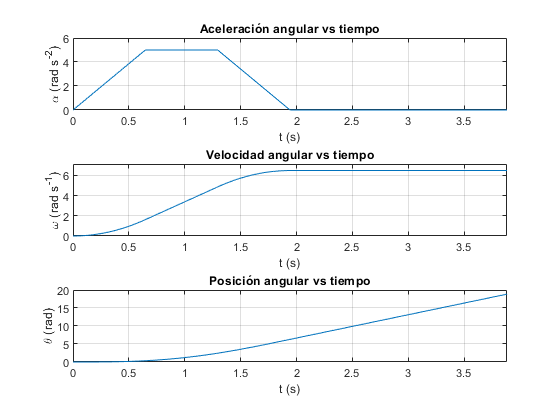

subplot(3,1,1)
plot(ts,aceleracion(ts))
title('Aceleración angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\alpha (rad s^{-2})')
ylim([0 6])
xlim([0 double(2*Tgiro)])
yticks(0:2:6)

subplot(3,1,2)
plot(ts,velocidad(ts))
title('Velocidad angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\omega (rad s^{-1})')
ylim([0 Vmax*1.1])
xlim([0 double(2*Tgiro)])
yticks(0:2:8)

subplot(3,1,3)
plot(ts,posicion(ts))
title('Posición angular vs tiempo')
grid on
xlabel('t (s)')
ylabel('\theta (rad)')
xlim([0 double(2*Tgiro)])

yticks(0:5:20)


TablaCinematica=table(double(ts)',double(aceleracion(ts))',double(velocidad(ts))',double(posicion(ts))');
TablaCinematica.Properties.VariableNames=["Tiempo","Aceleracion","Velocidad","Posicion"]
writetable(TablaCinematica,'Perfil_cinematica.txt','delimiter',' ', 'WriteVariableNames', true)
TablaTXT=table(double(ts)',double(velocidad(ts)*180/pi)');
writetable(TablaTXT,'Perfil_Velocidad.txt','delimiter',' ', 'WriteVariableNames', false)
clearvars -except Tgiro posicion aceleracion velocidad TablaCinematica